1. Convolution

Signal = [1,2,3,4];
Filter = [-1,1,-1,1];
Fold_Filter = Filter(end:-1:1);
Convol = [];
Zeros = zeros(1,size(Filter,2)-1);
Signal1 = [Zeros,Signal,Zeros];
Size = size(Filter,2)-1;
for i = 1:size(Signal1,2)-Size
        Convol = [Convol, dot(Fold_Filter,Signal1(i:i+Size))];    
end
Convol

Convol =     -1    -1    -2    -2     3    -1     4


2 .DFT

clc; clear all; close all;

N = 4; % length of the signal
b = (0:N-1)*2*pi/N; % row vector
mul = (0:N-1)';  % column vector
bm = exp(-1i * mul * b); % conjugate as basis vectors (row-wise)
DFTmatrix = sqrt(1/N) * bm; % Rows as conjugate of basis vectors (normalized)
DFTmatrix' * DFTmatrix % Identity matrix

ans =    1.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i
  -0.0000 + 0.0000i   1.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i  -0.0000 + 0.0000i   1.0000 + 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   1.0000 + 0.0000i


3. DCT

clc; clear all; close all;
N = 4; % length of the signal
% Create a row vector 'b'
b = (0:N-1)*pi/N + pi/(2*N);
% Create a column vector 'mul'
mul = (0:N-1)';
% Create the rowwise bases matrix 'D' using cosines
D = cos(mul * b);
% Normalize the rows of 'D'
D = [sqrt(1/N) * D(1, :); sqrt(2/N) * D(2:end, :)];
% Display the product of the transpose of 'D' with 'D'
D' * D

ans =     1.0000   -0.0000   -0.0000   -0.0000
   -0.0000    1.0000         0    0.0000
   -0.0000         0    1.0000   -0.0000
   -0.0000    0.0000   -0.0000    1.0000


4. FFT

% FFT of a signal without creating a function
signal = [1, 2, 3, 4];
N = length(signal);

% Create DFT matrix
b = (0:N-1)*2*pi/N;
mul = (0:N-1)';
bm = exp(-1i * mul * b);
DFTmatrix = sqrt(1/N) * bm;

% Compute FFT using DFT matrix multiplication
fft_result = DFTmatrix * signal(:);

disp('FFT Result:');

FFT Result:


disp(fft_result);

   5.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 0.0000i
  -1.0000 - 1.0000i



5. Image Grayscale

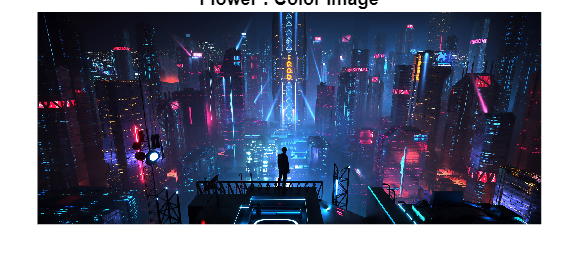

clc;
clear all;
close all;

im = imread("C:\Users\tarun\OneDrive\Pictures\Screenshots\SS.png"); % Provide the path to your color image
[m, n, d] = size(im);

imshow(im);
title("Flower : Color Image");

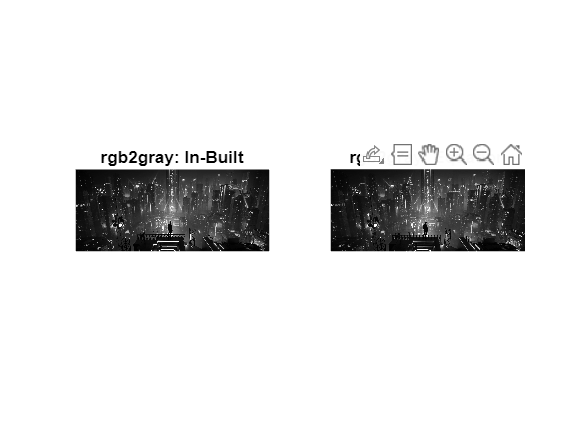


g1 = rgb2gray(im);
g2 = 0.3 * im(:, :, 1) + 0.6 * im(:, :, 2) + 0.1 * im(:, :, 3);

figure;
subplot(1, 2, 1);
imshow(g1);
title("rgb2gray: In-Built");

subplot(1, 2, 2);
imshow(g2);
title("rgb2gray: Equation");

6. Image Constrast

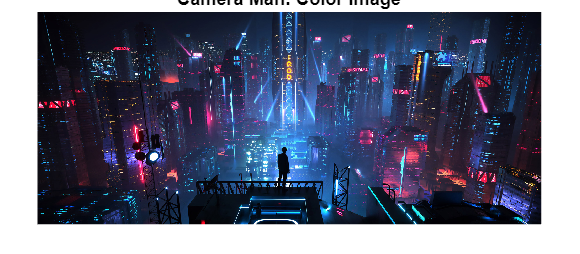

clc;
clear all;
close all;

im = imread("C:\Users\tarun\OneDrive\Pictures\Screenshots\SS.png");

imshow(im);
title("Camera Man: Color Image");

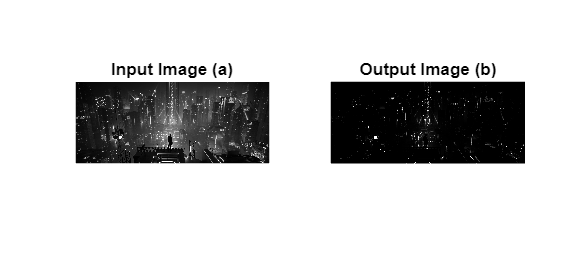


g1 = im2double(rgb2gray(im));
gamma = 4;
c = g1.^gamma;

subplot(1, 2, 1);
imshow(g1);
title('Input Image (a)');

subplot(1, 2, 2);
imshow(c);
title('Output Image (b)');

7. Median Filtering

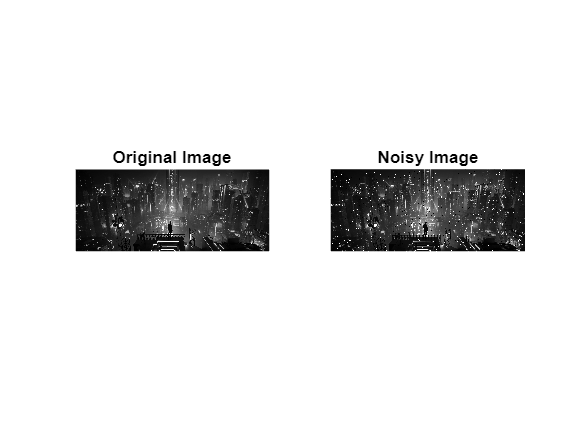

clc;
clear all;
close all;

im = imread("C:\Users\tarun\OneDrive\Pictures\Screenshots\SS.png");
im = im2double(rgb2gray(im));

im_noisy = imnoise(im, "salt & pepper", 0.02);

subplot(1, 2, 1);
imshow(im);
title('Original Image');

subplot(1, 2, 2);
imshow(im_noisy);
title('Noisy Image');

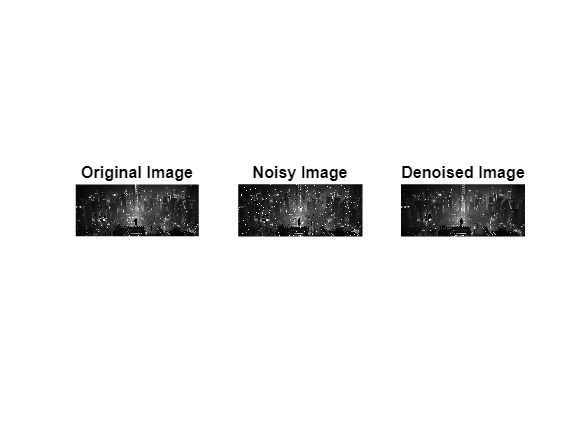


D = medfilt2(im_noisy);

figure;
subplot(1, 3, 1);
imshow(im);
title('Original Image');

subplot(1, 3, 2);
imshow(im_noisy);
title('Noisy Image');

subplot(1, 3, 3);
imshow(D);
title('Denoised Image');

8. Image Edge Extraction

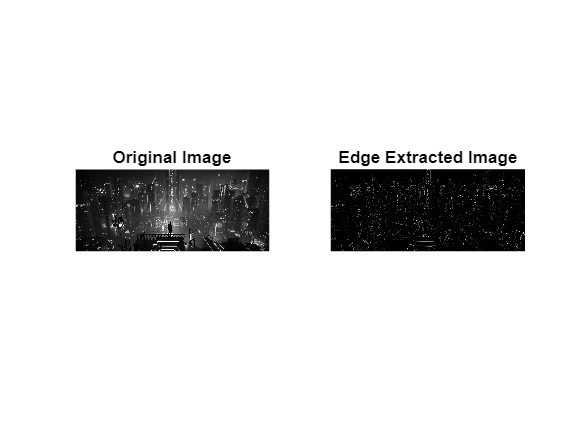

clc;
clear all;
close all;

im = imread("C:\Users\tarun\OneDrive\Pictures\Screenshots\SS.png");
im = im2double(rgb2gray(im));

f = [0 1 0; 1 -4 1; 0 1 0];
E = conv2(im, f, 'same');

subplot(1, 2, 1);
imshow(im);
title('Original Image');

subplot(1, 2, 2);
imshow(E);
title('Edge Extracted Image');

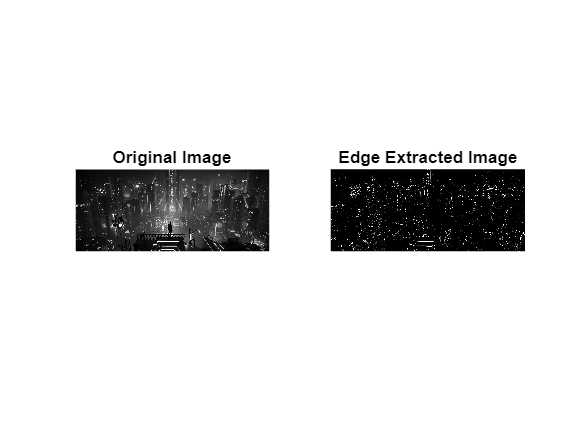


f = [1 1 1; 1 -9 1; 1 1 1];
E = conv2(im, f, 'same');

figure;
subplot(1, 2, 1);
imshow(im);
title('Original Image');

subplot(1, 2, 2);
imshow(E);
title('Edge Extracted Image');

9. FFT Image Reconstruction

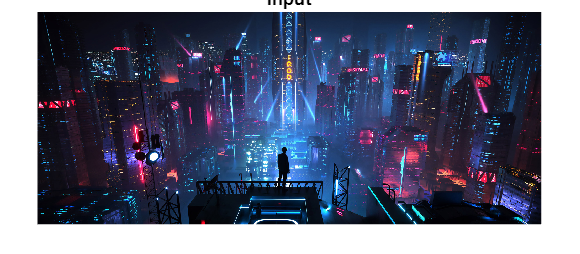

clc;
close all;
clear all;

f = imread("C:\Users\tarun\OneDrive\Pictures\Screenshots\SS.png");

imshow(f);
title('Input');

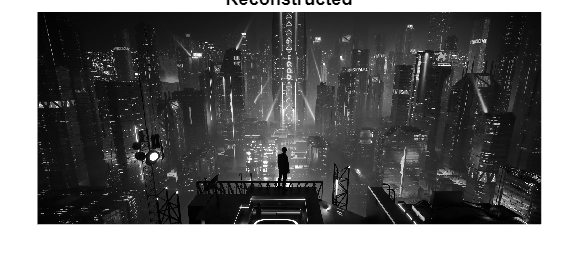


f = im2double(rgb2gray(f));
f1 = fft2(f);
f2 = ifft2(f1);

imshow(f2);
title('Reconstructed');


[M, N] = size(f);
wM = zeros(M, M);
wN = zeros(N, N);

for u = 0 : (M - 1)
    for x = 0 : (M - 1)
        wM(u + 1, x + 1) = exp(-2 * pi * 1i / M * x * u);
    end
end

for v = 0 : (N - 1)
    for y = 0 : (N - 1)
        wN(y + 1, v + 1) = exp(-2 * pi * 1i / N * y * v);
    end
end

F = wM * f * wN;

[M, N] = size(F);
wM = zeros(M, M);
wN = zeros(N, N);

for x = 0 : (M - 1)
    for u = 0 : (M - 1)
        wM(x + 1, u + 1) = exp(2 * pi * 1i / M * x * u);
    end
end

for y = 0 : (N - 1)
    for v = 0 : (N - 1)
        wN(v + 1, y + 1) = exp(2 * pi * 1i / N * y * v);
    end
end

g = (1 / (M * N)) * (wM * F * wN);
imshow(g);

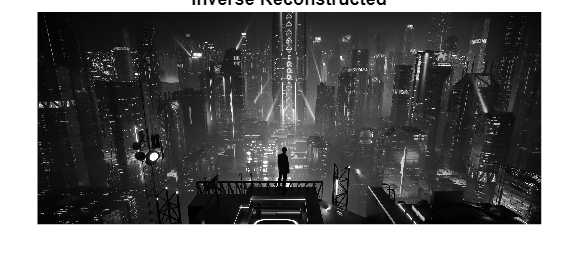

title('Inverse Reconstructed');

10. Average Window

%DFT Signal
duration = 50;
sampling_rate = 100;
t = linspace(0, duration, sampling_rate);
f = 10;
x = sin(2*pi*f*t);
subplot(6,2,1)
plot(t,x,'r')
title('Signal with 10Hz Frequency'); 
xlabel('Time (seconds)'); 
ylabel('Amplitude'); 

r = randn(1,size(x,2));
y = x + r;
subplot(6 ,2,2)
plot(t,y,'k')
title('Signal with 10Hz Frequency and Noise'); 
xlabel('Time (seconds)'); 
ylabel('Amplitude'); 

%Average of a given Window
window_sum = [];
for i = 1:96
      window_sum = [window_sum sum(y(i:i+4))/5];
end
Window_Sum1 = window_sum

Window_Sum1 =     1.0884    1.3158    1.1423    1.3483    1.3871    1.0375    0.7297    0.5061   -0.0403   -0.4011   -0.5999   -0.6589   -1.0158   -0.9921   -0.1632   -0.0740    0.0852    0.4266    0.6093    0.3137    0.6819    0.5185    0.5885    0.5538    0.2996   -0.1689   -0.2310   -0.1553   -0.3845   -0.2942   -0.0381   -0.0420   -0.5009   -0.2816   -0.1590   -0.1903    0.1520    0.6067    0.7662    1.0963    1.3792    1.2568    0.8061    0.8857    0.5327   -0.1133   -0.6498   -0.4359   -0.8109   -0.6563


subplot(6,2,3)
plot(1:96,window_sum,'m')
title('Window Sum Average');

%Average with Two zeros in the Front and Back
z = [0 0 y 0 0];
window = [];
for i = 4:99
      window = [window sum(z(i-3:i+3))/5];
end
Window_Sum2 = window

Window_Sum2 =     1.0884    1.4322    1.7370    2.0804    1.4896    1.2774    1.4646    1.1546    0.7243   -0.0537   -0.6708   -0.5814   -0.8986   -0.9975   -0.7229   -0.7045   -0.0951    0.1279    0.2707    0.6065    0.9695    0.5866    0.7904    0.7393    0.4796    0.1913    0.0419   -0.0468   -0.1638   -0.4032   -0.4006   -0.2998   -0.3788   -0.2143   -0.4068   -0.2064    0.1464    0.2661    0.5939    1.1904    1.4544    1.5622    1.2624    1.3276    1.1163    0.5749   -0.1839   -0.5527   -0.7401   -0.3460


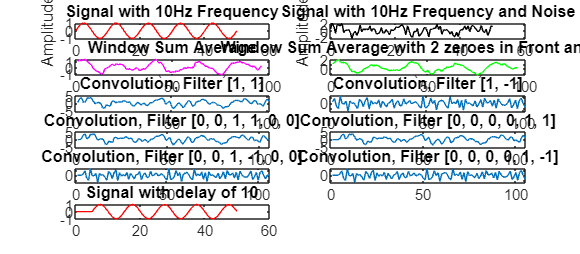

subplot(6,2,4)
plot(1:96,window,'g')
title('Window Sum Average with 2 zeroes in Front and Back');

%Convolve the signal
subplot(6, 2, 5);
Filter1 = [1,1];
Convol1 = convolve(y, Filter1);
plot(1:numel(Convol1), Convol1);
title("Convolution, Filter [1, 1]");

subplot(6, 2, 6);
Filter2 = [1, -1];
Convol2 = convolve(y, Filter2);
plot(1:numel(Convol2), Convol2);
title("Convolution, Filter [1, -1]");

subplot(6, 2, 7);
Filter3 = [0, 0, 1, 1, 0, 0];
Convol3 = convolve(y, Filter3);
plot(1:numel(Convol3), Convol3);
title("Convolution, Filter [0, 0, 1, 1, 0, 0]");

subplot(6, 2, 8);
Filter4 = [0, 0, 0, 0, 1, 1];
Convol4 = convolve(y, Filter4);
plot(1:numel(Convol4), Convol4);
title("Convolution, Filter [0, 0, 0, 0, 1, 1]");

subplot(6, 2, 9);
Filter5 = [0,0 0, 1, -1, 0, 0];
Convol5 = convolve(y, Filter5);
plot(1:numel(Convol5), Convol5);
title("Convolution, Filter [0, 0, 1, -1, 0, 0]");

subplot(6, 2, 10);
Filter6 = [0, 0, 0, 0, 1, -1];
Convol6 = convolve(y, Filter6);
plot(1:numel(Convol6), Convol6);
title("Convolution, Filter [0, 0, 0, 0, 1, -1]");

%Delay by Few Units
delay_amount = 10;
delayed_signal = [zeros(1, delay_amount), x(1:end - delay_amount)];
subplot(6,2,11)
plot(t,delayed_signal,'r')
title("Signal with delay of " + mat2str(delay_amount))

a = delayed_signal + r 

a =     0.5820    2.0797    0.6757   -1.5704    1.0007    0.7192    0.5789    1.5032   -1.1291   -0.0742    0.2118    1.0597    0.7784   -0.7189    1.1322    1.8838    0.5005    1.2575    2.8865    0.1921    0.5858   -0.3853   -0.6618   -1.3818   -0.4353   -2.1316   -1.1780   -1.1066   -2.0245   -1.3139   -0.2880    1.8297    0.5888    1.1971    2.3888    1.5247    0.5945    1.8662    1.0945    0.6910    1.0238    0.2057   -0.1836   -0.0024   -0.2675   -1.3503   -3.0230    0.1241   -0.9645   -1.8811


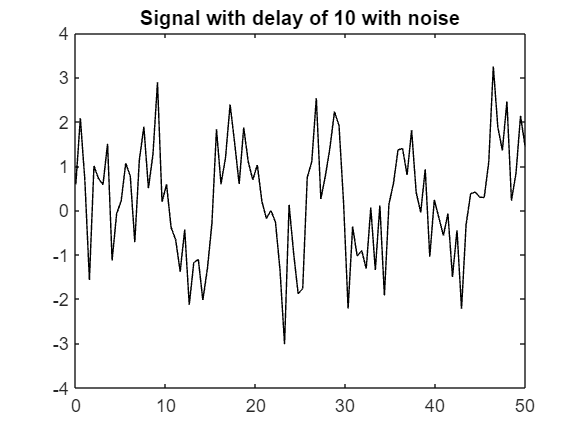

figure;
plot(t,a,'k')
title("Signal with delay of " + mat2str(delay_amount) + " with noise")

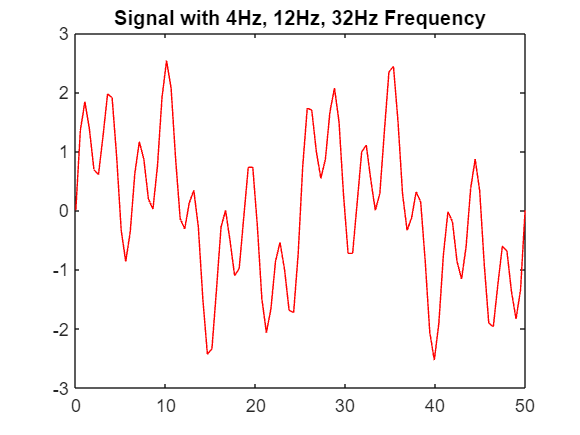


%Signal with multiple frequency
f1 = 4; f2 = 12; f3 = 32;
k = sin(2*pi*f1*t) + sin(2*pi*f2*t) + sin(2*pi*f3*t);
figure
plot(t,k,'r')
title('Signal with 4Hz, 12Hz, 32Hz Frequency');

function convolution = convolve(y, Filter)
    Fold_Filter = Filter(end:-1:1);
    Convol = [];
    Zeros = zeros(1, size(Filter, 2) - 1);
    y = [Zeros, y, Zeros];
    Size = size(Filter, 2) - 1;
    for i = 1:size(y, 2) - Size
        Convol = [Convol, dot(Fold_Filter, y(i:i+Size))];
    end
    convolution = Convol;
end